%added comment to prove change
close all; clear all; clc;


## Given and setup


M = [60.1429,18.5714;18.5714,14.2857]

M =    60.1429   18.5714
   18.5714   14.2857


D = [0, 0 ;0, 2]

D =      0     0
     0     2


K = [0, 0 ; 0, 1000]

K =            0           0
           0        1000


B = [1 ; 0 ]

B =      1
     0


F = [-0.042857;0.071429]

F =    -0.0429
    0.0714


$$q\_state = \left(\begin{array}{c} \bar{f\left(\theta \right)}\\ \bar{f\left(\varphi \right)} \end{array}\right)$$

$$q\_state\_dot = \left(\begin{array}{c} \frac{\partial }{\partial \theta }f\left(\theta \right)\\ \frac{\partial }{\partial \varphi }f\left(\varphi \right) \end{array}\right)$$

$$q\_state\_dot\_dot = \left(\begin{array}{c} \bar{\frac{\partial^{2}}{\partial \theta^{2}}f\left(\theta \right)}\\ \bar{\frac{\partial^{2}}{\partial \varphi^{2}}f\left(\varphi \right)} \end{array}\right)$$

$$big\_eqn = \begin{array}{l} \left(\begin{array}{c} \frac{92857\,\sigma_{2}}{5000}+\frac{1058045086050707\,\sigma_{1}}{17592186044416}=f\left(\mathrm{Tc}\right)-\frac{6176344615366955\,f\left(\mathrm{force}\right)}{144115188075855872}\\ 1000\,\bar{f\left(\varphi \right)}+\frac{8042134149590837\,\sigma_{2}}{562949953421312}+\frac{92857\,\sigma_{1}}{5000}+2\,\frac{\partial }{\partial \varphi }f\left(\varphi \right)=\frac{5147001884535155\,f\left(\mathrm{force}\right)}{72057594037927936} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial^{2}}{\partial \theta^{2}}f\left(\theta \right)}\\ \sigma_{2}=\bar{\frac{\partial^{2}}{\partial \varphi^{2}}f\left(\varphi \right)} \end{array}$$

C = 8.5511

## 1-state space

A = [0 1;-K(2,2)/C -D(2,2)/C]

A =          0    1.0000
 -116.9443   -0.2339


B_f = [0; (-F(1) +F(2))/C]

B_f =          0
    0.0134


B_Tc = [ 0 ; (-B(1)/C) ]

B_Tc =          0
   -0.1169


B = [B_f,B_Tc]

B =          0         0
    0.0134   -0.1169


C = [1 ,0]

C =      1     0



D = [0 ,0]

D =      0     0


## 2


[eig_vals,eig_vects] = eig(A)

eig_vals =   -0.0010 - 0.0921i  -0.0010 + 0.0921i
   0.9958 + 0.0000i   0.9958 + 0.0000i


eig_vects =   -0.1169 +10.8134i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.1169 -10.8134i


## 3


tf_final = ss(A,B,C,D)

tf_final =
 
  A = 
            x1       x2
   x1        0        1
   x2   -116.9  -0.2339
 
  B = 
            u1       u2
   x1        0        0
   x2  0.01337  -0.1169
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



[wn,zeta,poles] = damp(tf_final)

wn =    10.8141
   10.8141


zeta =     0.0108
    0.0108


poles =   -0.1169 +10.8134i
  -0.1169 -10.8134i



control_mat_both = ctrb(A,B);
trust_torque_bool = length(control_mat_both)-rank(control_mat_both) == 0

trust_torque_bool = logical
   0



control_mat_thrust = ctrb(A,B_f);
thrust_bool = length(control_mat_thrust)-rank(control_mat_thrust) == 0

thrust_bool = logical
   1



control_mat_torque = ctrb(A,B_Tc);
torque_bool = length(control_mat_torque)-rank(control_mat_torque) == 0

torque_bool = logical
   1



observe_sensor = obsv(A,C)

observe_sensor =      1     0
     0     1


sensor_bool = length(observe_sensor)-rank(observe_sensor) == 0

sensor_bool = logical
   1


## 4 settime - 30; %OS - 16;

B_nof = [0, 0; B_Tc'] % only the torquer

B_nof =          0         0
         0   -0.1169


rank(ctrb(A,B_nof)) % system controllability

ans = 2


% choose new eigenvalues based on performance for an appropriate gain controller
ts = 30; % settling time in seconds
OS = 16/100; % 16 percent overshoot

% zeta = -ln(OS)/sqrt(pi^2 + ln^2(OS))
% Ts = 4 / zeta*wn

syms zeta w_n
damping_ratio_condition = OS == exp(-pi*zeta/sqrt(1-power(zeta,2)));
zeta = vpa(solve(damping_ratio_condition,zeta));

spec_zeta = double(zeta(1)) % system damping ratio

spec_zeta = 0.5039

settling_time_condition = ts == 4 / (zeta(1) * w_n);
spec_wn = double(vpa(solve(settling_time_condition,w_n))) % natural frequency (radians/second)

spec_wn = 0.2646


% find poles
poles_spec = [-spec_zeta*spec_wn + spec_wn*i*sqrt(1-power(spec_zeta,2)); -spec_zeta(1)*spec_wn - spec_wn*i*sqrt(1-power(spec_zeta,2))]

poles_spec =   -0.1333 + 0.2286i
  -0.1333 - 0.2286i


% These poles are the new eigenvalues for our system specifications, placed
% as G (our controllable/regulator gain.) 
G = place(A,B_nof,poles_spec) 

G =          0         0
  999.4012   -0.2803



A_cl = A-(B_nof*G);
cPlant = ss(A_cl,B_nof,C,0) % new Ax + Bu

cPlant =
 
  A = 
             x1        x2
   x1         0         1
   x2  -0.07002   -0.2667
 
  B = 
            u1       u2
   x1        0        0
   x2        0  -0.1169
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



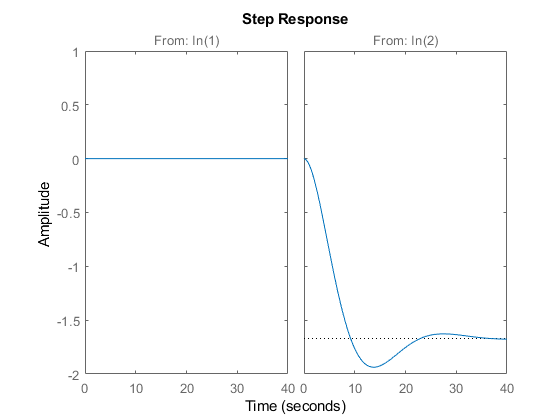

step(cPlant)

stepinfo(cPlant)

ans = 1×2 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


## 4b

poles_est = poles_spec*2;
bPlant = place(A,B, poles_est)

bPlant =  -112.5423    0.2889
  984.7429   -2.5276



A_obs = A_cl'

A_obs =          0   -0.0700
    1.0000   -0.2667


C_obs = B_nof'

C_obs =          0         0
         0   -0.1169


B_obs = C'

B_obs =      1
     0



bPlant = place(A_obs,B_obs, poles_est)

bPlant =     0.2667    0.1390




syms s L_1 L_2 L_3
poles_est_eqn = vpa(prod(expand(s*poles_est)),5)

$$poles\_est\_eqn = 0.28009\,s^{2}$$


L_mat = [0 L_1; 0 L_2]

$$L\_mat = \left(\begin{array}{cc} 0 & L_{1}\\ 0 & L_{2} \end{array}\right)$$

eqn_1_obs = vpa(A_obs - L_mat * C_obs,5)

$$eqn\_1\_obs = \left(\begin{array}{cc} 0 & 0.11694\,L_{1}-0.070023\\ 1.0 & 0.11694\,L_{2}-0.26667 \end{array}\right)$$

eqn_2_obs = eye(size(A_obs))*s - eqn_1_obs

$$eqn\_2\_obs = \left(\begin{array}{cc} s & 0.070023488292250135600625071674585-0.11694434261622177473327610641718\,L_{1}\\ -1.0 & s-0.11694434261622177473327610641718\,L_{2}+0.2666666666666515084216371178627 \end{array}\right)$$


L_1_answer = vpa(solve(vpa(det(eqn_2_obs) == poles_est_eqn,5),L_1),5) == L_1

$$L\_1\_answer = 2.2802870211667785803351587785971\,s-1.0\,L_{2}\,s+6.1559715564311417467801356575303\,s^{2}+0.59877619323619100047255280438467=L_{1}$$

L_2_answer = vpa(solve(vpa(det(eqn_2_obs) == poles_est_eqn,5),L_2),5) == L_2

$$L\_2\_answer = \frac{8.5510763293759057486703468750689\,\left(0.71990604683099945759749971330166\,s^{2}+0.2666666666666515084216371178627\,s-0.11694434261622177473327610641718\,L_{1}+0.070023488292250135600625071674585\right)}{s}=L_{2}$$


mat = equationsToMatrix([L_1_answer,L_2_answer],[L_1, L_2])

$$mat = \left(\begin{array}{cc} -1.0 & -1.0\,s\\ -\frac{1.0}{s} & -1.0 \end{array}\right)$$

linsolve(mat,[L_1;L_2])

$$ans = \left(\begin{array}{c} \infty \\ \infty \end{array}\right)$$



error_vals = [-100:100]

error_vals =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


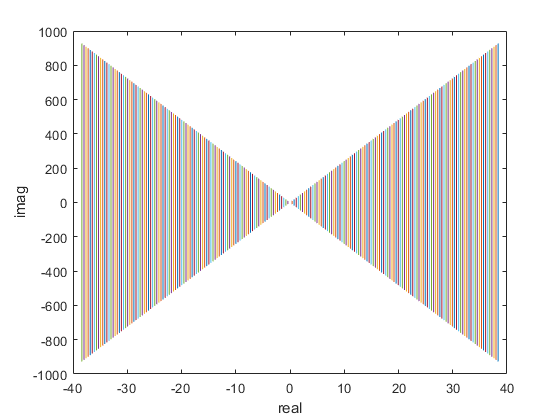

plot(real(eig((A-bPlant*C')) *error_vals),imag(eig((A-bPlant*C')) *error_vals))
xlabel('real')
ylabel('imag')

**4C**